%%Worksheet 1 - Arithmetic and Algebraic Manipulation

%1)a)
sym((5/12)+(2/3)+(3/4))

$$ans = \frac{11}{6}$$


%b)
sym(((9/24)*6)+((11/12)*4))

$$ans = \frac{71}{12}$$


%2)
h1 = 8+(5/8)-2+(7/9)

h1 =    7.402777777777778


h2 = 5+(3/8)+2+(5/7)

h2 =    8.089285714285714


h1-h2

ans =   -0.686507936507936


sym(h1-h2)

$$ans = -\frac{173}{252}$$

%3)a)
(-2)^6

ans = 64


%b)
-2^6

ans = -64


%c)
(3^3) * (3^5) * (3^(-7))

ans = 3


%d)
(4^6)*((4^(-7))/(4^(-5)))

ans = 256


%e)
sym((5^5 * 5^-3)/(5^4 * 5^-2 * 5^3))

$$ans = \frac{1}{125}$$

%%% I have not found an easy way of returning an answer in the form of a
%%% power of 2.
%4)a)
2^4 / 2

ans = 8


%b)
(2^3)^4

ans = 4096

2^12 %added this to check it had done the calculation I wanted it to.

ans = 4096


%c)
sym(sqrt(2))

$$ans = \sqrt{2}$$

sym(2^(1/2))

$$ans = \sqrt{2}$$

%5)a)
syms y %this fucntion creates a symbolic variable
simplify(y^5 * y^8)

$$ans = y^{13}$$

%%% Not sure why this is not printing an answer on the right hand side

%b)
syms c
simplify (c^7 / c^4)

$$ans = c^{3}$$


%c)
syms x
simplify (x^3 / x)

$$ans = x^{2}$$


%d)
syms z
simplify (z^4 / z^6)

$$ans = \frac{1}{z^{2}}$$


%e)
syms a
var = simplify (a^3)^2

$$var = a^{6}$$

var %attempted to get this to print by saving the answer and calling it but this doesnt seem to work either. The variable however is however present in the workspace.

$$var = a^{6}$$

%6)a)
isAlways(7+3*2 == (7+3)*2)

ans = logical
   0



%b)
isAlways((6/3)+4 == 6/(3+4))

ans = logical
   0



%c)
isAlways((3/4)/5 == 3/(4/5))

ans = logical
   0



%d)
(3^4)^5 == (3^5)^4

ans = logical
   1


%%7)a)
syms x y z real
isAlways((x+y)+z == x+(y+z))

ans = logical
   1



%b)
isAlways((x-y)-z == x-(y-z))

ans = logical
   0



%c)
isAlways((x-y)^2 == (x^2-y^2))

ans = logical
   0



%d)
isAlways((x*y)^2 == x^2*y^2)

ans = logical
   1



%e)
isAlways(sqrt(x*y) ==sqrt(x)*sqrt(y))

ans = logical
   0


%8)a)
syms y(x)
m = 6; % setting gradient
c = 2; % setting y intercept
y(x) = m*x+c % stating function

$$y(x) = 6\,x+2$$

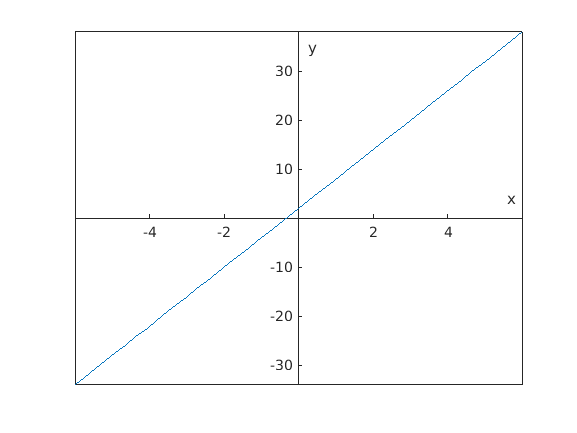

fplot(y,[-6 6]) % plots graph and sets range of x axis
%%% How to set ranges y range?
xlabel("x") %naming axes
ylabel("y")
ax=gca; %The following lines forces axes to cross at the origin
ax.XAxisLocation = "origin"; % centers x axis on origin
ax.YAxisLocation = "origin"; % centers y axis on origin

%box off %removes outer box around graph


%b)
syms y(x)
m = -3; % gradient
c = 1; % y intercept
y = m*x+c % function

$$y = 1-3\,x$$

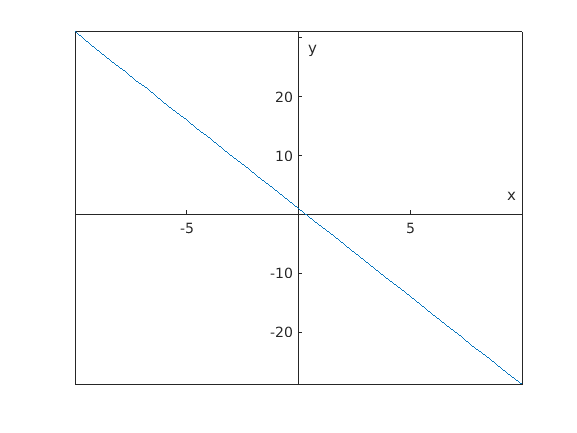

fplot(y,[-10 10])
%centres on origin
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
xlabel("x")
ylabel("y")

%c)
syms y(x)
%testing creating the function without declaring m & c separately
y(x) = 2*x -1

$$y(x) = 2\,x-1$$

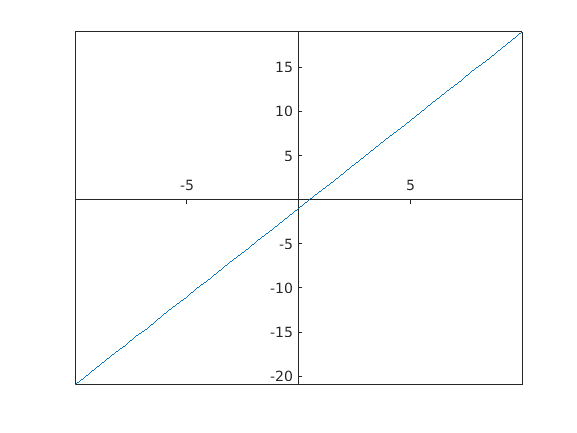

fplot(y, [-10 10]) %plotting function and setting x range
%centering on origin
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";

%ax % this function can be used to show a variety of axis information

%%Testing plotting a quadratic equation
syms y(x)
y(x) = 2*x^2 + 2*x + 10

$$y(x) = 2\,x^{2}+2\,x+10$$

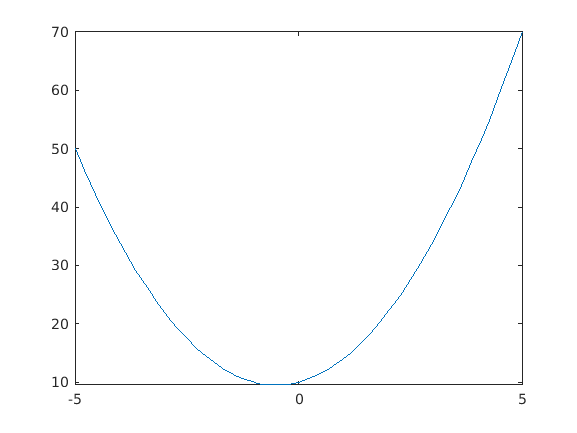

fplot(y)

%9)a)
syms x
solve(6*x-4 == 8, x) %solving for x

$$ans = 2$$


%b)
syms x
solve(6*x-4 == 9*x+8, x)

$$ans = -4$$


%c)
syms x
solve(3*(x+2*(x-2))-2*(x-3*(x-1)) == 0, x)

$$ans = \frac{18}{13}$$


%d)
syms x
solve(((x-7)/3)+((2*x-1)/4) == (x+3)/6, x)

$$ans = \frac{37}{8}$$


%e)
syms x
solve((x/2)-((2+3*x)/5) == 1+(x/4), x)

$$ans = -4$$

%10)a)
syms p v r t
solve(p*v == r*t, v)

$$ans = \frac{r\,t}{p}$$


%b)
solve(p*v == r*t, r)

$$ans = \frac{p\,v}{t}$$


%c)
solve(p*v == r*t, t)

$$ans = \frac{p\,v}{r}$$


%d)
solve(p*v == r*t, p)

$$ans = \frac{r\,t}{v}$$

%11)
syms T v g e
solve(T == (2*v/g)*(1/(1-e)),e)

$$ans = 1-\frac{2\,v}{T\,g}$$

%12)
%checking an operation I did wasnt wrong
syms u v
isAlways((1-(u/v) == (v-u)/v))

ans = logical
   1



%checking answer to question
syms u v c d n
solve(u == v*(1-(c/(d*sqrt(n)))),n)

$$ans = \frac{c^{2}}{d^{2}\,{\left(\frac{u}{v}-1\right)}^{2}}$$


%since the answer is slightly different from whats on my paper I am
%checking the two
isAlways(ans == (c*v/(d*v-d*u))^2)

ans = logical
   1


%%%here I am assuming ans will always take the last answer before the
%%%calculation that uses it?

%13)a)
syms x y
soln = solve([4*x+5*y == 4, x-y == 1], [x y])

soln = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]


soln.x

$$ans = 1$$

soln.y

$$ans = 0$$


%b)
syms x y
soln = solve([3*x-4*y ==-3, 2*x+9*y == 5], [x y])

soln = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]


soln.x

$$ans = -\frac{1}{5}$$

soln.y

$$ans = \frac{3}{5}$$


%c)
syms x y
soln = solve([1.23*x+4.56*y == 7.89, -0.12*x-3.45*y == -6.78], [x y])

soln = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]


soln.x

$$ans = -1$$

soln.y

$$ans = 2$$


%d)
syms x y 
soln = solve([80 == x+y, 83 == (21/20)*x+(103/100)*y], [x y])

soln = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]


soln.x

$$ans = 30$$

soln.y

$$ans = 50$$


%e)
syms a b
soln = solve([9*a+7*b == 287, 7*a+9*b == 305], [a b])

soln = struct with fields:
    a: [1×1 sym]
    b: [1×1 sym]


soln.a

$$ans = 14$$

soln.b

$$ans = 23$$

%f)
syms a11 a12 a21 a22 b1 b2 x1 x2
soln = solve([a11*x1+a12*x2 == b2, a21*x1+a22*x2 ==b2], [x y])

soln = struct with fields:
    x: [0×1 sym]
    y: [0×1 sym]


soln.x

 
ans =
 
Empty sym: 0-by-1
 


soln.y

 
ans =
 
Empty sym: 0-by-1
 



%%%Not happy with answer

%14)
((0.056/0.15)*(0.035/0.0023)) / (0.14/4.5)

ans = 182.6087